cd 'C:\GitHub\CVUT-MatLab\grant'
startup

## Sections

crossSectionsSet.import = importdata("sectionsSet.mat");
crossSectionsSet.A = cat(1, table2array(crossSectionsSet.import.RHS(:,"A")), table2array(crossSectionsSet.import.L(:,"A")));
crossSectionsSet.Iy = cat(1, table2array(crossSectionsSet.import.RHS(:,"Iy")), table2array(crossSectionsSet.import.L(:,"Iu")));
crossSectionsSet.Iz = cat(1, table2array(crossSectionsSet.import.RHS(:,"Iz")), table2array(crossSectionsSet.import.L(:,"Iv")));
crossSectionsSet.Ip = cat(1, table2array(crossSectionsSet.import.RHS(:,"Ip")), table2array(crossSectionsSet.import.L(:,"Ip")));

sections.id = ones(112,1)*9;

% sections.id = sectionsID;
[s,~] = size(sections.id);
for j = 1:s
    sections.A(j,1)  = crossSectionsSet.A(sections.id(j));
    sections.Iy(j,1) = crossSectionsSet.Iy(sections.id(j));
    sections.Iz(j,1) = crossSectionsSet.Iz(sections.id(j));
    sections.Ix(j,1) = crossSectionsSet.Ip(sections.id(j));
    sections.E(j,1)  = 210*10^9;
    sections.v(j,1)  = 0.3;
end

ndisc = 7;


## Nodes

width = 2.9;
length = 2.9;
height = 3;
topHeight = 20;
nbricks = 7;
nodes.x = [[0;length;length;0];kron(ones(nbricks,1),[0;length;length;0])];                          % x coordinates of nodes
nodes.y = [[0;0;width;width];kron(ones(nbricks,1),[0;0;width;width])];                              % y coordinates of nodes
nodes.z  = [0;0;0;0];                                                                               % z coordinates of nodes
for i = 1:nbricks
    nodes.z  = [nodes.z; [height;height;height;height] + (i-1) .* [height;height;height;height]];   % z coordinates of nodes
end
nodes.z((nbricks)*4+1:(nbricks+1)*4) =[topHeight;topHeight;topHeight;topHeight];                    % z coordinates of nodes
nnodes = numel(nodes.x); 

## Supports

kinematic.x.nodes = [1;2;3;4];              % node indices with restricted x-direction displacements
kinematic.y.nodes = [1;2;3;4];              % node indices with restricted y-direction displacements
kinematic.z.nodes = [1;2;3;4];              % node indices with restricted z-direction displacements
kinematic.rx.nodes = [];                    % node indices with restricted x-direction displacements
kinematic.ry.nodes = [];                   % node indices with restricted y-direction displacements
kinematic.rz.nodes = [];                    % node indices with restricted z-direction displacements

nodes.dofs = true(nnodes,6);                % no kinematic boundary conditions
nodes.dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction
nodes.dofs(kinematic.rx.nodes,4) = false;    % mark prevented movement in x-direction
nodes.dofs(kinematic.ry.nodes,5) = false;    % mark prevented movement in y-direction
nodes.dofs(kinematic.rz.nodes,6) = false;    % mark prevented movement in z-direction

## Beams

modulNodes1 = [1;2;3;4; 1;2;2;3;3;4;4;1; 5;6;7;8  ];   % elements starting nodes
beams.nodesHead = (reshape(kron(modulNodes1', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(modulNodes1))*4);
% beams.nodesHead = modulNodes1;
modulNodes2 = [5;6;7;8; 6;5;7;6;8;7;5;8; 6;7;8;5  ];   % elements ending nodes
beams.nodesEnd = (reshape(kron(modulNodes2', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(modulNodes2))*4);
% beams.nodesEnd = modulNodes2;
nr = numel(beams.nodesHead);

### Beams sections

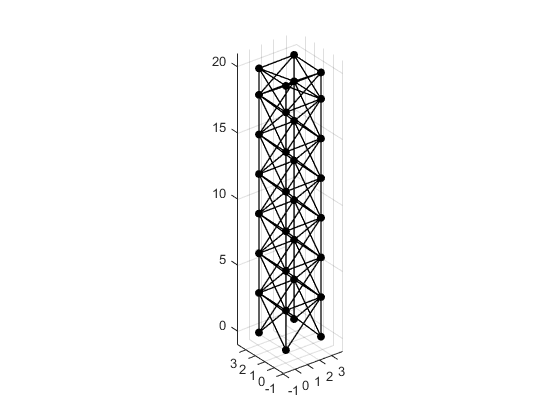

beams.disc      = ones(nr,1)*ndisc;
modulElemGroup = [1;2;3;4; 5;6;7;8;9;10;11;12;  13;14;15;16];
beams.sections = reshape(kron(modulElemGroup', ones(nbricks, 1))', 1, [])';
plot3([nodes.x(beams.nodesHead) nodes.x(beams.nodesEnd)]', ...
     [nodes.y(beams.nodesHead) nodes.y(beams.nodesEnd)]', ...
     [nodes.z(beams.nodesHead) nodes.z(beams.nodesEnd)]', ...
     'k','LineWidth',1);
hold on;
scatter3(nodes.x, nodes.y, nodes.z, 'black', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
zlim([min(nodes.z)-1,max(nodes.z)+1]);  % to avoid tight limits
grid on
hold off

## Loads

loads.y.nodes = reshape((repmat([1,2], nbricks, 1) + (1:nbricks)'*4).',1,[])';             % node indices with x-direction forces
loads.y.value = ones(nbricks*2,1)*0.5;             % magnitude of the x-direction forces
loads.x.nodes = [[1;2;3;4]+(nbricks)*4; reshape((repmat([1,4], nbricks, 1) + (1:nbricks)'*4).',1,[])'];            % node indices with y-direction forces
loads.x.value = [[10;10;10;10]*10^3; -ones(nbricks*2,1)*0.5];             % magnitude of the y-direction forces 
loads.z.nodes = [1;2;3;4]+(nbricks)*4;             % node indices with y-direction forces
loads.z.value = [-10;-10;-10;-10]*10^3;             % magnitude of the y-direction forces 

loads.rx.nodes = [];          % node indices with x-direction forces
loads.rx.value = [];          % magnitude of the x-direction forces
loads.ry.nodes = [];          % node indices with y-direction forces
loads.ry.value = [];          % magnitude of the y-direction forces 
loads.rz.nodes = [];          % node indices with z-direction forces
loads.rz.value = []; 

## Force vector

forceVector = sparse([loads.x.nodes*6-5; loads.y.nodes*6-4; loads.z.nodes*6-3;loads.rx.nodes*3-2; loads.ry.nodes*3-1; loads.rz.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value;loads.rx.value; loads.ry.value; loads.rz.value], ...
                     nnodes*6, 1);
f = forceVector(reshape(reshape(nodes.dofs.',[],1).', 1, [])');
of = f;
% f = full(f)

## FEM

nodes.ndofs = sum(sum(nodes.dofs));
nodes.nnodes    = nnodes;

beams.nbeams  = nr;
beams.vertex = beamVertexFn(beams,nodes);
beams.codeNumbers = codeNumbersFn(beams,nodes);
beams.XY = XYtoBeamsFn(beams);

elements = discretizationBeamsFn(beams,nodes);
elements.XY = XYtoElementFn(beams);
elements.sections = sectionToElementFn(sections,beams);
elements.ndofs = max(max(elements.codeNumbers));



%------------------------------------------------------------------------
%   Linear analysis
%------------------------------------------------------------------------
endForces.global = sparse(elements.ndofs,1);
endForces.global(1:max(max(beams.codeNumbers))) = f;

transformationMatrix = transformationMatrixFn(elements);

stiffnesMatrix = stiffnessMatrixFn(elements,transformationMatrix);

[endForces.local, displ] = EndForcesFn(stiffnesMatrix,endForces,transformationMatrix,elements);
%------------------------------------------------------------------------
%   Non-linear analysis
%------------------------------------------------------------------------
geometricMatrix = geometricMatrixFnV2(elements,transformationMatrix,endForces);

volume = sum(elements.sections.A .* transformationMatrix.lengths)

volume = 0.8791


Results = criticalLoadFn(stiffnesMatrix,geometricMatrix,10);

[sortedValues,sortedVectors]= sortValuesVectorFn(Results.values,Results.vectors);


disp('1. kritické břemeno')

1. kritické břemeno


disp([num2str(sortedValues(1)),' N'])

15.8616 N


disp('2. kritické břemeno')

2. kritické břemeno


disp([num2str(sortedValues(2)),' N'])

16.7629 N


disp('3. kritické břemeno')

3. kritické břemeno


disp([num2str(sortedValues(3)),' N'])

-18.1979 N


disp('4. kritické břemeno')

4. kritické břemeno


disp([num2str(sortedValues(4)),' N'])

18.2198 N


disp('5. kritické břemeno')

5. kritické břemeno


disp([num2str(sortedValues(5)),' N'])

18.2545 N


disp('6. kritické břemeno')

6. kritické břemeno


disp([num2str(sortedValues(6)),' N'])

-19.2906 N


disp('7. kritické břemeno')

7. kritické břemeno


disp([num2str(sortedValues(7)),' N'])

-20.8529 N


disp('8. kritické břemeno')

8. kritické břemeno


disp([num2str(sortedValues(8)),' N'])

-21.002 N


disp('9. kritické břemeno')

9. kritické břemeno


disp([num2str(sortedValues(9)),' N'])

23.8466 N


disp('10. kritické břemeno')

10. kritické břemeno


disp([num2str(sortedValues(10)),' N'])

24.2594 N
